# **Hopf Fibration Charts Investigation**

clc; clear; close all;

## **Preliminaries**

#### **Basis Vectors and Function Definitions**

e3 = [0;0;1];
e2 = [0;1;0];
e1 = [1;0;0];
qmul = @(p,q) [ ...
    p(1)*q(1) - p(2)*q(2) - p(3)*q(3) - p(4)*q(4);
    p(1)*q(2) + p(2)*q(1) + p(3)*q(4) - p(4)*q(3);
    p(1)*q(3) - p(2)*q(4) + p(3)*q(1) + p(4)*q(2);
    p(1)*q(4) + p(2)*q(3) - p(3)*q(2) + p(4)*q(1) ];
qabc = @(a,b,c) [ ...
    sqrt((1+c)/2);
   -b / sqrt(2*(1+c));
    a / sqrt(2*(1+c));
    0 ];
qabc_bar = @(a,b,c) [ ...
   -b / sqrt(2*(1-c));
    sqrt((1-c)/2);
    0;
    a / sqrt(2*(1-c))];
qyaw = @(yaw) [cos(yaw/2); 0; 0; sin(yaw/2)];
qconj = @(q) [q(1); -q(2:4)];
qrot = @(q, x) qmul(qmul(q, [0; x]), qconj(q));

#### **Chart 1 Symbolic Definition**

syms a b c real
assumeAlso(a^2 + b^2 + c^2 == 1)
assumeAlso(c > -1)
q = (1/(2*sqrt(1+c))) * [1+c; -b; a; 0];
q = simplify(q);
pretty(q)

/   sqrt(c + 1)   \
|   -----------   |
|        2        |
|                 |
|         b       |
| - ------------- |
|   2 sqrt(c + 1) |
|                 |
|        a        |
|  -------------  |
|  2 sqrt(c + 1)  |
|                 |
\        0        /



#### **Chart 2 Symbolic Definition**

syms a b c real
assumeAlso(a^2 + b^2 + c^2 == 1)
assumeAlso(c < 1)
q = (1/(2*sqrt(1-c))) * [-b; 1-c; 0; a];
q = simplify(q /norm(q));
pretty(q)

/       sqrt(2) b     \
|   - -------------   |
|     2 sqrt(1 - c)   |
|                     |
| sqrt(2) sqrt(1 - c) |
| ------------------- |
|          2          |
|                     |
|          0          |
|                     |
|      sqrt(2) a      |
|    -------------    |
\    2 sqrt(1 - c)    /



## Chart Visualization

#### Chart 1

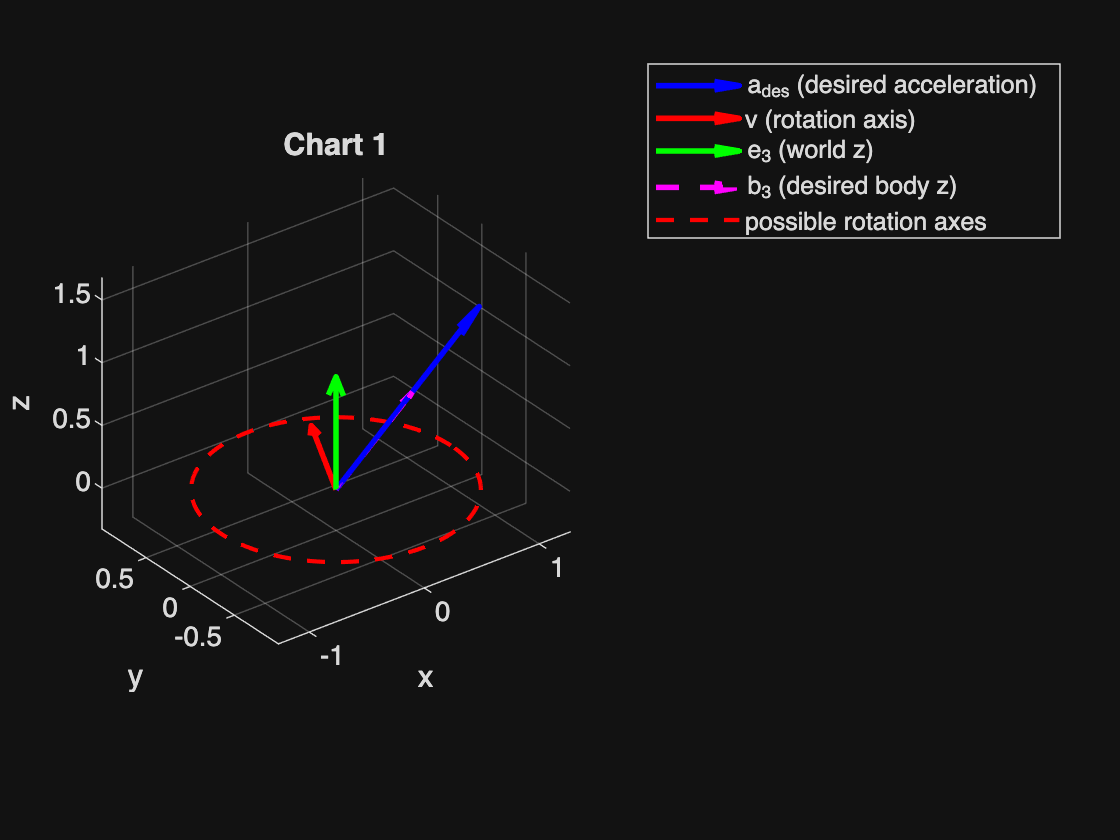

% a_des in upper hemisphere
a_des = [1;-0.5;1.5];
s = a_des / norm(a_des);
a = s(1);
b = s(2);
c = s(3);

% quaternion vector part
v = [-b; a; 0];
v = v / norm(v);

% rotated vector using the chart 1 quaternion
q = qabc(a, b, c);
b3 = qrot(q, e3);

% circle of possible chart 1 rotation axes
theta = linspace(0, 2*pi, 500);
circle_x = cos(theta);
circle_y = sin(theta);
circle_z = zeros(size(theta));

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart 1');

% plot t (blue)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(0,0,0,v(1),v(2),v(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3 (green)
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5);
% rotated e3 (magenta)
quiver3(0,0,0,b3(2),b3(3),b3(4),'LineWidth',2,'Color','m','MaxHeadSize',0.5,'LineStyle','--');
% circle with rotation axis
plot3(circle_x, circle_y, circle_z,'r--','LineWidth',1.5);
% legend
legend('a_{des} (desired acceleration)', ...
       'v (rotation axis)', ...
       'e_3 (world z)', ...
       'b_3 (desired body z)', ...
       'possible rotation axes');

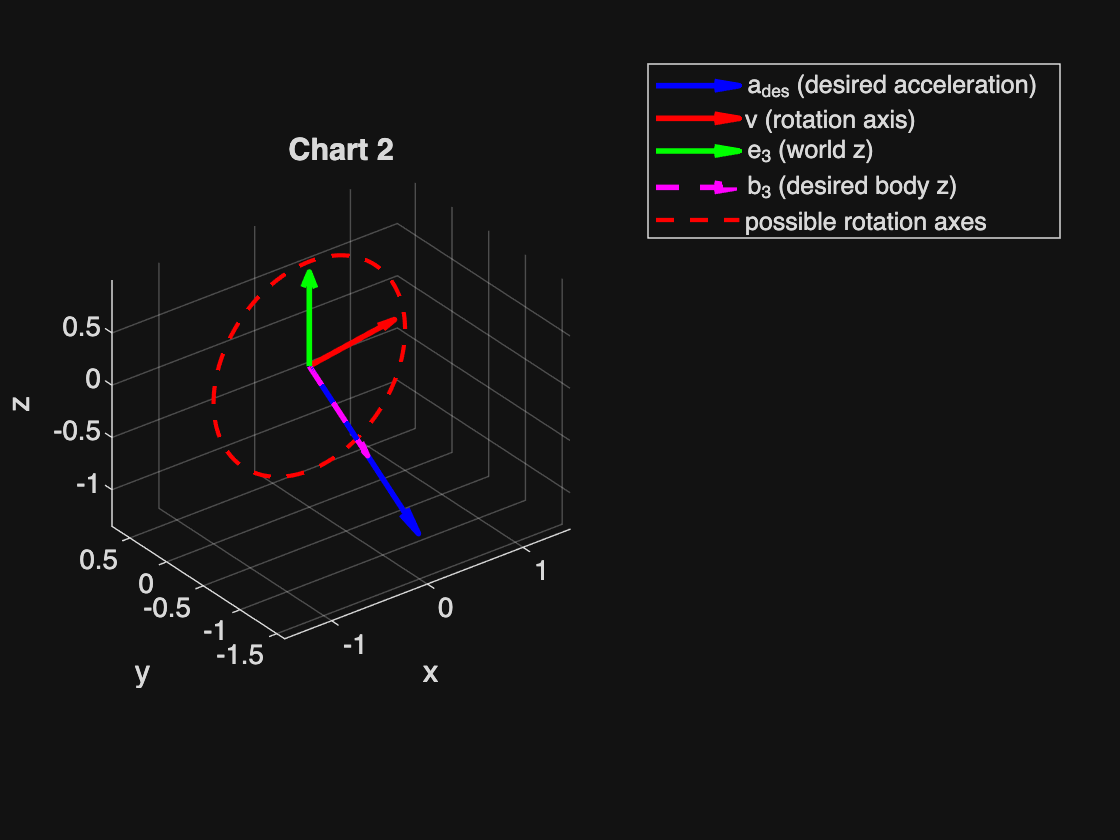

% a_des in lower hemisphere
a_des = -[-0.5;1;1.5];
s = a_des / norm(a_des);
a = s(1);
b = s(2);
c = s(3);

% quaternion vector part
v = [1-c; 0; a];
v = v / norm(v);

% rotated vector using the chart 2 quaternion
q = qabc_bar(a, b, c);
b3 = qrot(q, e3);

% circle of possible chart 2 rotation axes
theta = linspace(0, 2*pi, 500);
circle_x = cos(theta);
circle_y = zeros(size(theta)); 
circle_z = sin(theta);

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart 2');

% plot t (blue)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(0,0,0,v(1),v(2),v(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3 (green)
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5);
% rotated e3 (magenta)
quiver3(0,0,0,b3(2),b3(3),b3(4),'LineWidth',2,'Color','m','MaxHeadSize',0.5,'LineStyle','--');
% circle with rotation axis
plot3(circle_x, circle_y, circle_z,'r--','LineWidth',1.5);
% legend
legend('a_{des} (desired acceleration)', ...
       'v (rotation axis)', ...
       'e_3 (world z)', ...
       'b_3 (desired body z)', ...
       'possible rotation axes');

#### Chart 3

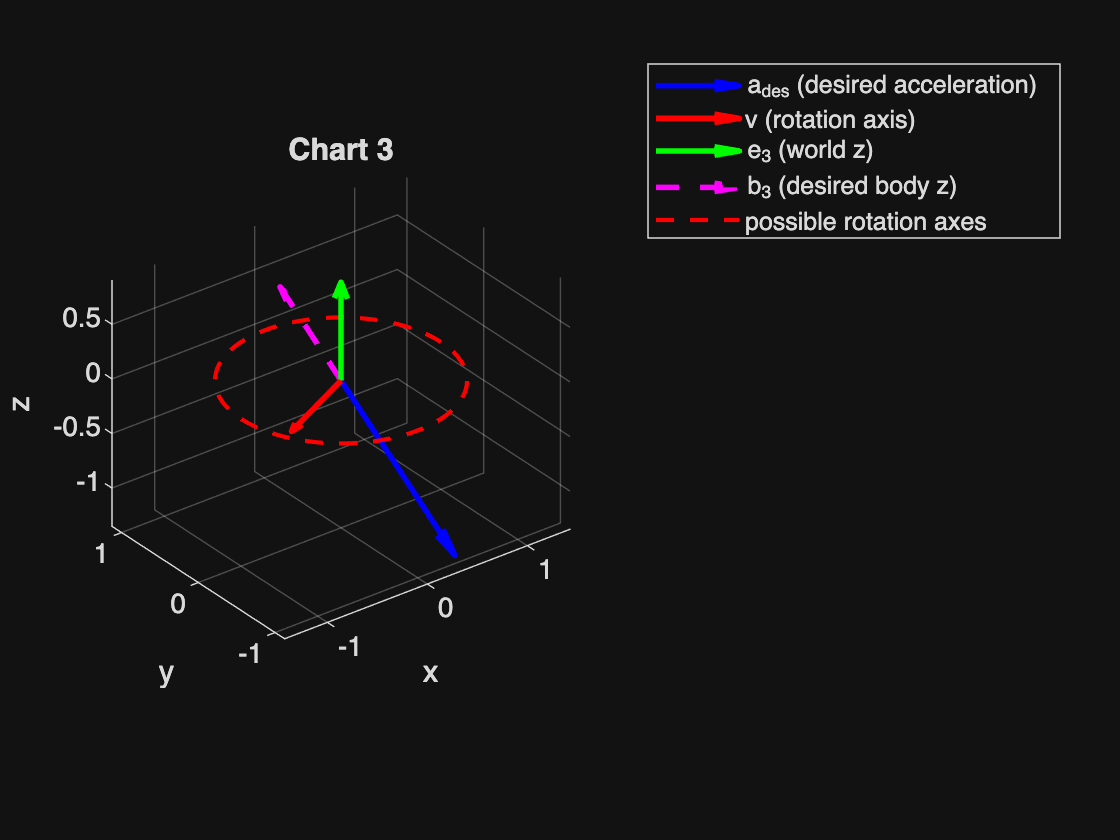

% a_des in lower hemisphere
a_des = -[-0.5;1;1.5];
s = -1 * a_des / norm(a_des);
a = s(1);
b = s(2);
c = s(3);

% quaternion vector part
v = [-b; a; 0];
v = v / norm(v);

% rotated vector using the chart 1 quaternion
q = qabc(a, b, c);
b3 = qrot(q, e3);

% circle of possible chart 1 rotation axes
theta = linspace(0, 2*pi, 500);
circle_x = cos(theta);
circle_y = sin(theta);
circle_z = zeros(size(theta));

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart 3');

% plot t (blue)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(0,0,0,v(1),v(2),v(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3 (green)
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5);
% rotated e3 (magenta)
quiver3(0,0,0,b3(2),b3(3),b3(4),'LineWidth',2,'Color','m','MaxHeadSize',0.5,'LineStyle','--');
% circle with rotation axis
plot3(circle_x, circle_y, circle_z,'r--','LineWidth',1.5);
% legend
legend('a_{des} (desired acceleration)', ...
       'v (rotation axis)', ...
       'e_3 (world z)', ...
       'b_3 (desired body z)', ...
       'possible rotation axes');

#### Chart 4

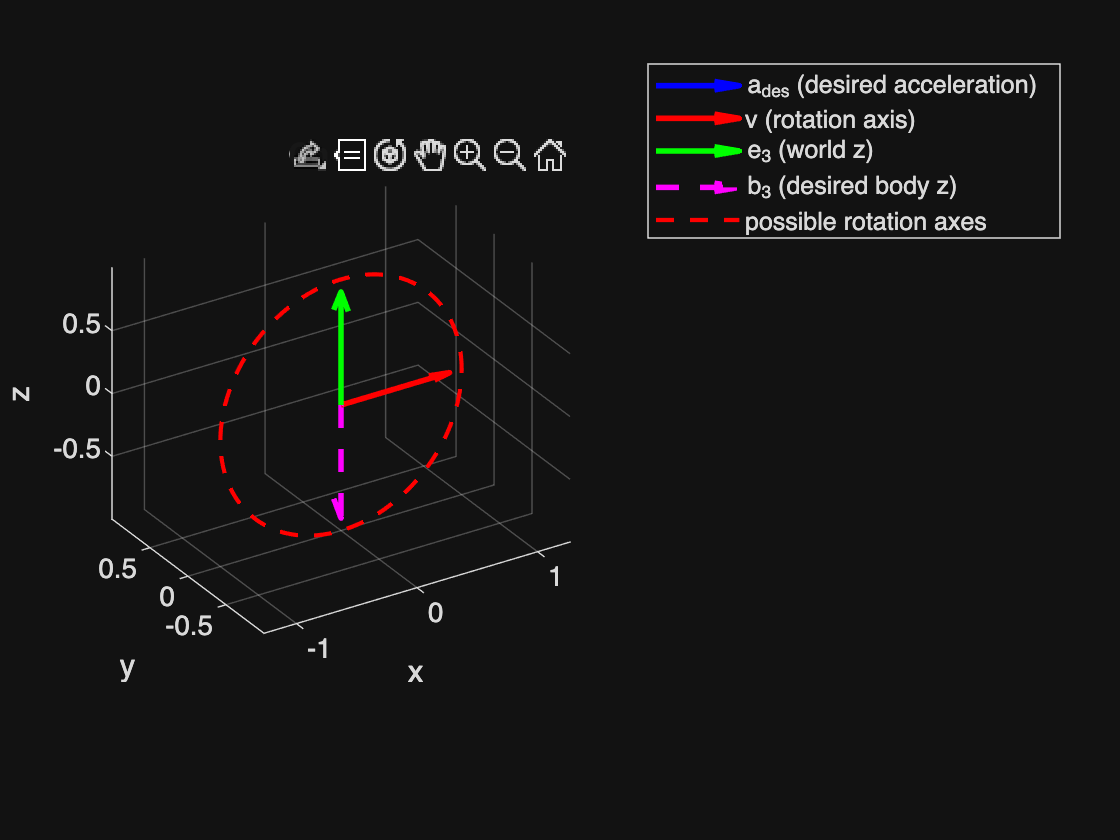

% a_des in upper hemisphere
a_des = [0;0;1];
s = -1 * a_des / norm(a_des);
a = s(1);
b = s(2);
c = s(3);

% quaternion vector part
v = [1-c; 0; a];
v = v / norm(v);

% rotated vector using the chart 2 quaternion
q = qabc_bar(a, b, c);
b3 = qrot(q, e3);

% circle of possible chart 2 rotation axes
theta = linspace(0, 2*pi, 500);
circle_x = cos(theta);
circle_y = zeros(size(theta)); 
circle_z = sin(theta);

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart 4');

% plot t (blue)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5);
% plot n (red)
quiver3(0,0,0,v(1),v(2),v(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5);
% reference e3 (green)
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5);
% rotated e3 (magenta)
quiver3(0,0,0,b3(2),b3(3),b3(4),'LineWidth',2,'Color','m','MaxHeadSize',0.5,'LineStyle','--');
% circle with rotation axis
plot3(circle_x, circle_y, circle_z,'r--','LineWidth',1.5);
% legend
legend('a_{des} (desired acceleration)', ...
       'v (rotation axis)', ...
       'e_3 (world z)', ...
       'b_3 (desired body z)', ...
       'possible rotation axes');

## Chart Transitions

#### Step Command Flip

- a_des = [0;0;1];

- eta_1 =  1; (chart 1)

- eta_2 = -1; (chart 4)

- yaw_des = *anything*

**Insight: ***We need to account for the sign change in eta for the chart transition in yaw because of the order of the quaternion multiplications. When we first apply q_abc, a negative eta will flip the rotation axis that q_psi will act on. Thus, to account for this, we can negate the yaw to get the same rotation in the world frame.  *

#### Chart Switch Parameters

a_des = [0;0;2];
eta_1 = 1; % chart 1
eta_2 = -1; % chart 4
yaw_des = 5*pi/4; % in the world frame from trajectory

#### SO(3) Visualization

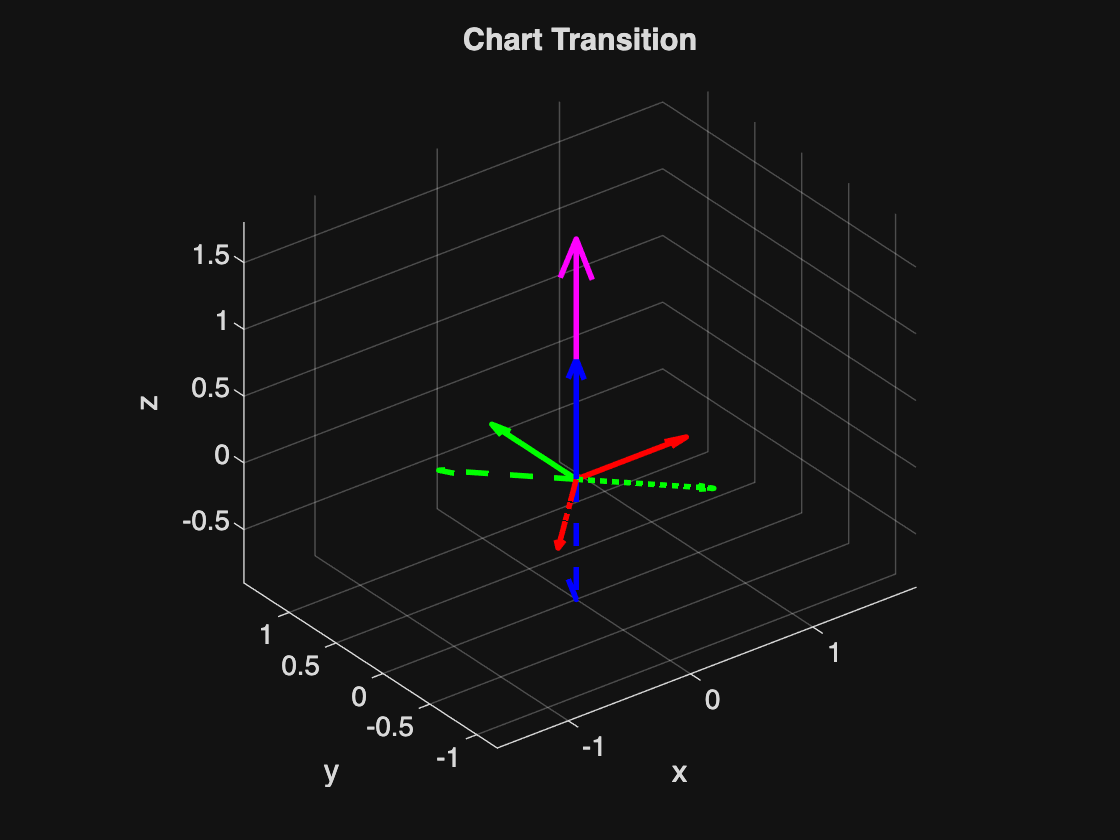

% chart 1 quaternion multiplications
s = eta_1 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
q_abc = qabc(a, b, c);
q_yaw = qyaw(eta_1*yaw_des);
q_1 = qmul(q_abc, q_yaw);

% chart 2 quaternion multiplications
s = eta_2 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
if eta_1 ~= eta_2
    yaw_offset = 0.0;
else 
    yaw_offset = 2*atan2(a, b);
end
q_abc_bar = qabc_bar(a, b, c);
yaw_bar = eta_2*yaw_des + yaw_offset;
q_yaw_bar = qyaw(yaw_bar);
q_2 = qmul(q_abc_bar, q_yaw_bar);

% chart 1 body frame
b1_1 = qrot(q_1, e1);
b2_1 = qrot(q_1, e2);
b3_1 = qrot(q_1, e3);

% chart 2 body frame
b1_2 = qrot(q_2, e1);
b2_2 = qrot(q_2, e2);
b3_2 = qrot(q_2, e3);

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart Transition')

% plot a_des (magenta)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','m','MaxHeadSize',0.5);

% world frame (-)
quiver3(0,0,0,e1(1),e1(2),e1(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e2(1),e2(2),e2(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','-');

% chart 1 body frame (:)
quiver3(0,0,0,b1_1(2),b1_1(3),b1_1(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b2_1(2),b2_1(3),b2_1(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b3_1(2),b3_1(3),b3_1(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle',':');

% chart 2 body frame (--)
quiver3(0,0,0,b1_2(2),b1_2(3),b1_2(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b2_2(2),b2_2(3),b2_2(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b3_2(2),b3_2(3),b3_2(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','--');

#### Flip and Normal Chart Transition

- a_des = [1;1;0];

- eta =  1; (chart 1)

- eta =  -1; (chart 2)

- yaw_des = *anything*

#### Chart Switch Parameters

a_des = [1;0.5;0];
eta_1 = 1;
eta_2 = -1;
yaw_des = -3*pi/5;

#### SO(3) Visualization

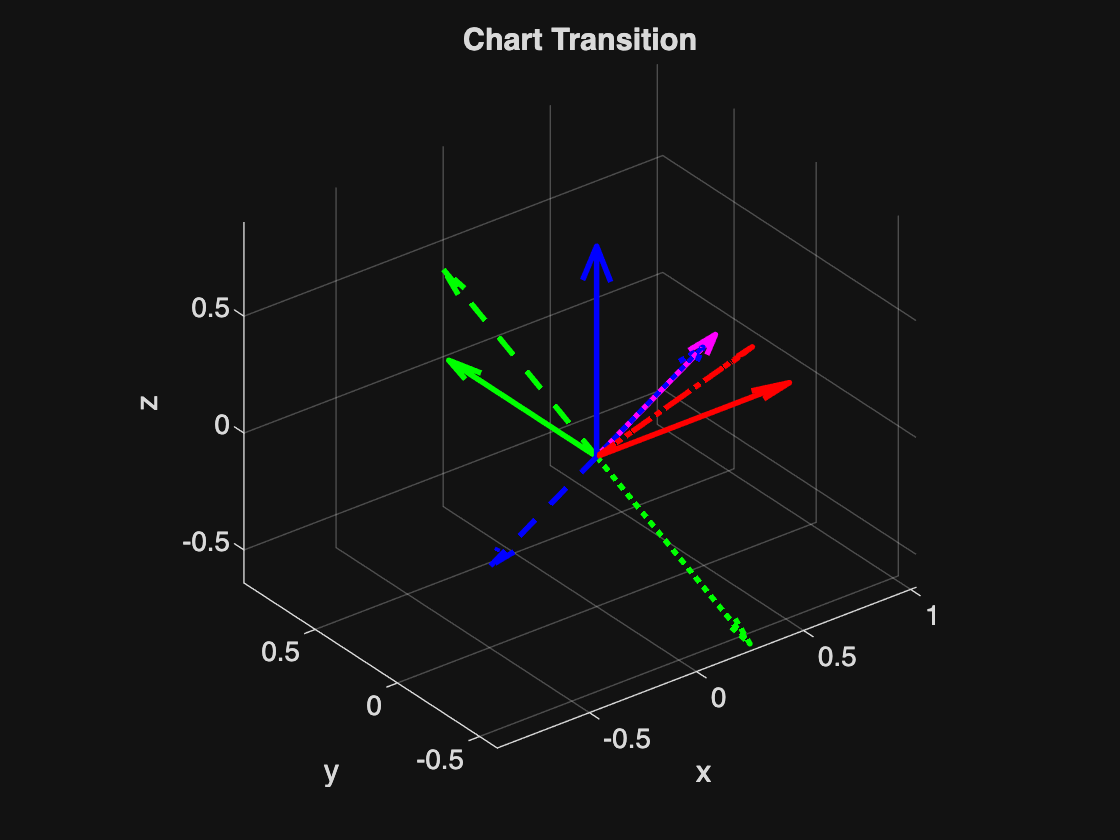

% chart 1 quaternion multiplications
s = eta_1 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
q_abc = qabc(a, b, c);
q_yaw = qyaw(eta_1*yaw_des);
q_1 = qmul(q_abc, q_yaw);

% chart 2 quaternion multiplications
s = eta_2 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
if eta_1 ~= eta_2
    yaw_offset = 0.0;
else 
    yaw_offset = 2*atan2(a, b);
end
% yaw_offset = 2*atan2(a, b);
q_abc_bar = qabc_bar(a, b, c);
yaw_bar = eta_2* yaw_des + yaw_offset;
q_yaw_bar = qyaw(yaw_bar);
q_2 = qmul(q_abc_bar, q_yaw_bar);

% chart 1 body frame
b1_1 = qrot(q_1, e1);
b2_1 = qrot(q_1, e2);
b3_1 = qrot(q_1, e3);

% chart 2 body frame
b1_2 = qrot(q_2, e1);
b2_2 = qrot(q_2, e2);
b3_2 = qrot(q_2, e3);

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart Transition')

% plot a_des (magenta)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','m','MaxHeadSize',0.5);

% world frame (-)
quiver3(0,0,0,e1(1),e1(2),e1(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e2(1),e2(2),e2(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','-');

% chart 1 body frame (:)
quiver3(0,0,0,b1_1(2),b1_1(3),b1_1(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b2_1(2),b2_1(3),b2_1(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b3_1(2),b3_1(3),b3_1(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle',':');

% chart 2 body frame (--)
quiver3(0,0,0,b1_2(2),b1_2(3),b1_2(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b2_2(2),b2_2(3),b2_2(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b3_2(2),b3_2(3),b3_2(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','--');

#### Normal Chart Transition

- a_des = [1;1;0];

- eta =  1; (chart 1)

- eta =  -1; (chart 2)

- yaw_des = *anything*

#### Chart Switch Parameters

a_des = [1;1;0];
eta_1 = 1;
eta_2 = 1;
yaw_des = -pi/4;

#### SO(3) Visualization

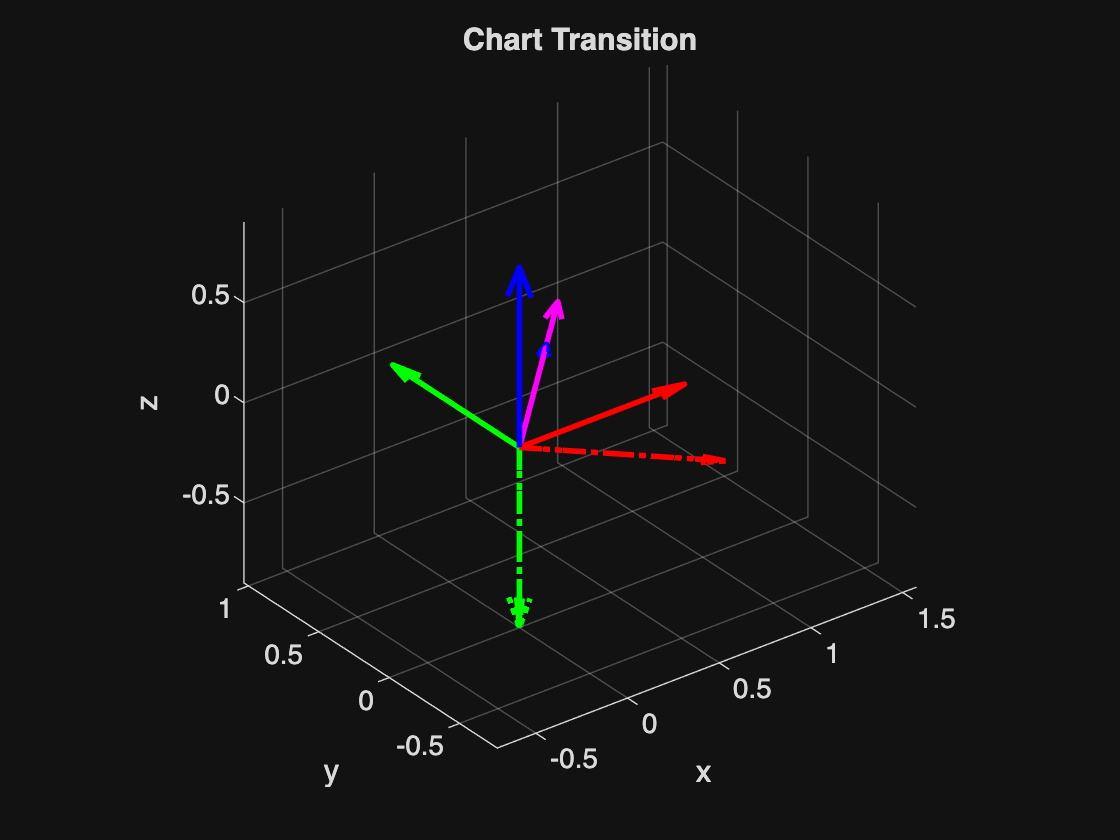

% chart 1 quaternion multiplications
s = eta_1 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
q_abc = qabc(a, b, c);
q_yaw = qyaw(eta_1*yaw_des);
q_1 = qmul(q_abc, q_yaw);

% chart 2 quaternion multiplications
s = eta_2 * a_des / norm(a_des);
a = s(1); 
b = s(2); 
c = s(3);
if eta_1 ~= eta_2
    yaw_offset = 0.0;
else 
    yaw_offset = 2*atan2(a, b);
end
% yaw_offset = 2*atan2(a, b);
q_abc_bar = qabc_bar(a, b, c);
yaw_bar = eta_2*yaw_des + yaw_offset;
q_yaw_bar = qyaw(yaw_bar);
q_2 = qmul(q_abc_bar, q_yaw_bar);

% chart 1 body frame
b1_1 = qrot(q_1, e1);
b2_1 = qrot(q_1, e2);
b3_1 = qrot(q_1, e3);

% chart 2 body frame
b1_2 = qrot(q_2, e1);
b2_2 = qrot(q_2, e2);
b3_2 = qrot(q_2, e3);

% plot
figure; hold on; grid on; axis equal;
xlabel('x'); ylabel('y'); zlabel('z'); view(3);
title('Chart Transition')

% plot a_des (magenta)
quiver3(0,0,0,a_des(1),a_des(2),a_des(3),'LineWidth',2,'Color','m','MaxHeadSize',0.5);

% world frame (-)
quiver3(0,0,0,e1(1),e1(2),e1(3),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e2(1),e2(2),e2(3),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','-');
quiver3(0,0,0,e3(1),e3(2),e3(3),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','-');

% chart 1 body frame (:)
quiver3(0,0,0,b1_1(2),b1_1(3),b1_1(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b2_1(2),b2_1(3),b2_1(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle',':');
quiver3(0,0,0,b3_1(2),b3_1(3),b3_1(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle',':');

% chart 2 body frame (--)
quiver3(0,0,0,b1_2(2),b1_2(3),b1_2(4),'LineWidth',2,'Color','r','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b2_2(2),b2_2(3),b2_2(4),'LineWidth',2,'Color','g','MaxHeadSize',0.5,'LineStyle','--');
quiver3(0,0,0,b3_2(2),b3_2(3),b3_2(4),'LineWidth',2,'Color','b','MaxHeadSize',0.5,'LineStyle','--');

#### Additional S1 Visualization

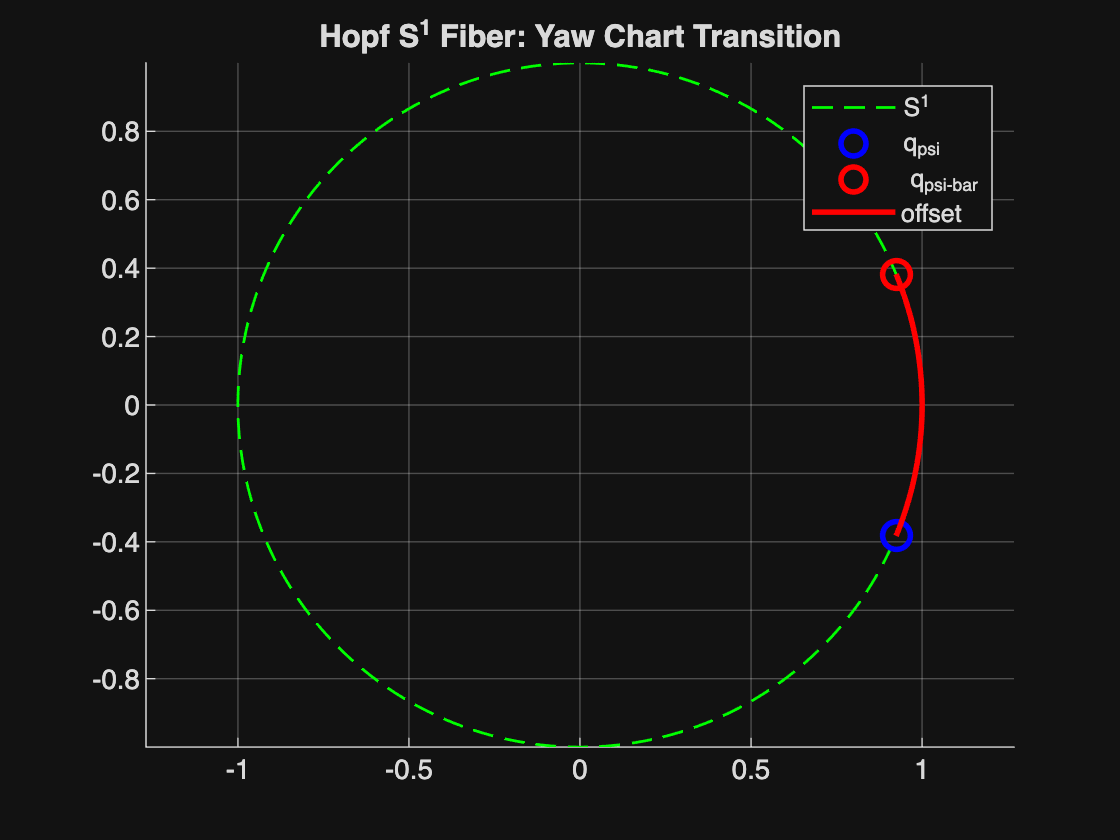

% plot S1
theta = linspace(0,2*pi,400);
figure; hold on; axis equal; grid on;
plot(cos(theta), sin(theta), 'g--', 'LineWidth', 1);

% plot points
plot(q_yaw(1),     q_yaw(4),     'bo', 'MarkerSize',10, 'LineWidth',2);
plot(q_yaw_bar(1), q_yaw_bar(4), 'ro', 'MarkerSize',10, 'LineWidth',2);

% draw arc showing offset
arc_theta = linspace(yaw_des/2, yaw_bar/2, 100);
plot(cos(arc_theta), sin(arc_theta), 'r', 'LineWidth',2);

legend('S^1','q_{psi}',' q_{psi-bar}','offset');
title('Hopf S^1 Fiber: Yaw Chart Transition');